clear all
syms theta1 theta2 theta3 theta4 theta5 theta6 ;
N = 5000 ;
theta1_min = -180 ; theta1_max = 180 ; 
theta2_min = -180 ; theta2_max = 180 ; 
theta3_min = -180 ; theta3_max = 180 ; 
theta4_min = -180 ; theta4_max = 180 ; 
theta5_min = -180 ; theta5_max = 180 ; 
theta6_min = -180 ; theta6_max = 180 ; 

t1 = theta1_min + (theta1_max-theta1_min)*rand(N,1); 
t2 = theta2_min + (theta2_max-theta2_min)*rand(N,1); 
t3 = theta3_min + (theta3_max-theta3_min)*rand(N,1); 
t4 = theta4_min + (theta4_max-theta4_min)*rand(N,1); 
t5 = theta5_min + (theta5_max-theta5_min)*rand(N,1); 
t6 = theta6_min + (theta6_max-theta6_min)*rand(N,1); 


alpha = [90 0 0 -90 90 0] ; 
a = [0 40 30 0 0 0] ; 
d = [0 0 0 10 10 50] ;
T0_1 = T_matrix(theta1,alpha(1),a(1),d(1)) ;
T1_2 = T_matrix(theta2,alpha(2),a(2),d(2)) ;
T2_3 = T_matrix(theta3,alpha(3),a(3),d(3)) ;
T3_4 = T_matrix(theta4,alpha(4),a(4),d(4)) ;
T4_5 = T_matrix(theta5,alpha(4),a(4),d(4)) ;
T5_6 = T_matrix(theta6,alpha(5),a(5),d(5)) ;
T0_6 = T0_1*T1_2*T2_3*T3_4*T4_5*T5_6 ;

A = [] ;
B = [] ;
C = [] ;
for i = 1:N
    theta1 = t1(i) ;
    theta2 = t2(i) ;
    theta3 = t3(i) ;
    theta4 = t4(i) ;
    theta5 = t5(i) ;
    theta6 = t6(i) ;
    x = T0_6(1,4) ;
    y = T0_6(2,4) ;
    z = T0_6(3,4) ; 
    A = [A,vpa(subs(x),2)] ;
    B = [B,vpa(subs(y),2)] ; 
    C = [C,vpa(subs(z),2)] ;

end

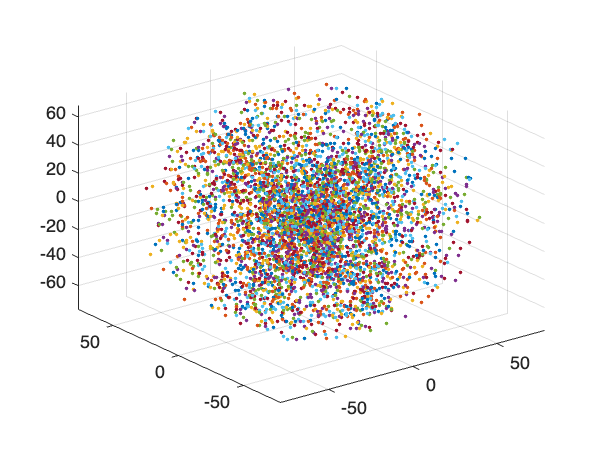

fplot3(A,B,C,'.') ;

function T = T_matrix(theta,alpha,a,d) 
    T = [cos(theta) -cos(alpha)*sin(theta) sin(alpha)*sin(theta) a*cos(theta) ;
        sin(theta) cos(alpha)*cos(theta) -sin(alpha)*cos(theta) a*sin(theta) ;
        0 sin(alpha) cos(alpha) d ;
        0 0 0 1] ;
end